% 810101361
% Aij--->N(1,0.6)----->(100,1000)
% Xij--->N(3,0.1)----->(1000,1)
% Nij--->N(0,1)----->(100,1)

%each time we Run the code we have same matrixes
s=rng; 
% Generate random matrices A, X, and N
A = 1 + sqrt(0.6)*randn(100,1000);
X = 3 + sqrt(0.1)*randn(1000,1);
N = randn(100,1);
rng(s);

% Compute Y
Y = A * X + N;



A_hat=Y*pinv(X);
y_hat=A_hat*X;

num_repeats = 100;
errors = zeros(num_repeats, 1);
for i = 1:num_repeats
    A1 = 1 + sqrt(0.6)*randn(100,1000);
    X1 = 3 + sqrt(0.1)*randn(1000,1);
    % Generate new random noise
    N2 = randn(100,1);
    % Recompute Y
    Y1 = A1*X1 + N2;
    % Recompute X_ls and error
    A_hat1 = Y1*pinv(X1);
    errors(i) = norm(A1 - A_hat1)/norm(A1);
end







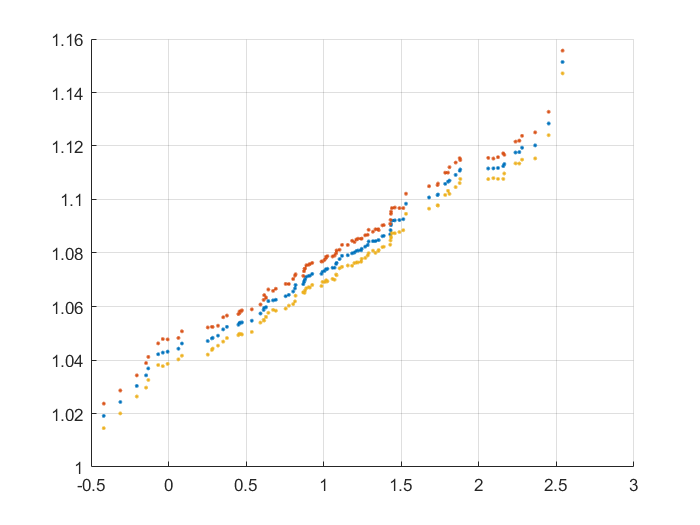

cov_A_hat=((errors'*errors)*(X'*X)^-1)/(100-1);
errbar=sqrt(diag(X*cov_A_hat*X'));
u=X(1:100,1);

figure;
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1)),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1))+errbar(1:100,1),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1))-errbar(1:100,1),'.');
grid
hold off

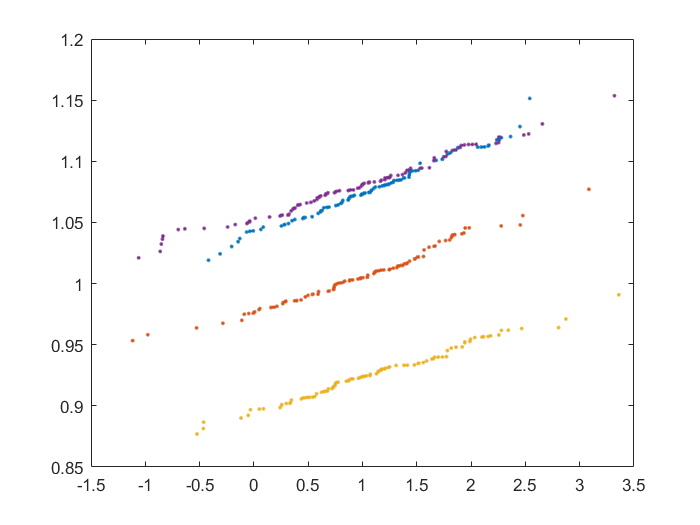

plot(sort(A(1:100,1:4)),sort(A_hat(1:100,1:4)),'.');

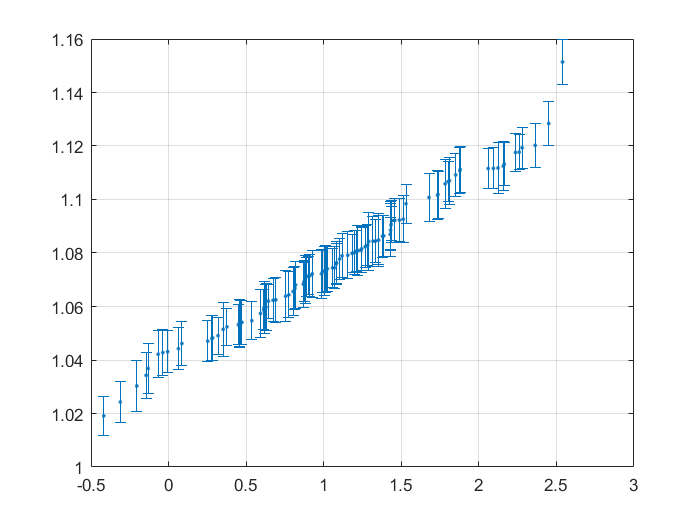


% Calculate the 95% confidence interval
alpha = 0.05;
z = norminv(1 - alpha/2);
ci = z * se;

% plot 
A_sorted = sort(A(1:100,1));
A_hat_sorted = sort(A_hat(1:100,1));
errbar_sorted = sort(errbar);

figure;
errorbar(A_sorted, A_hat_sorted, ci(1:100,:), '.');
grid on;

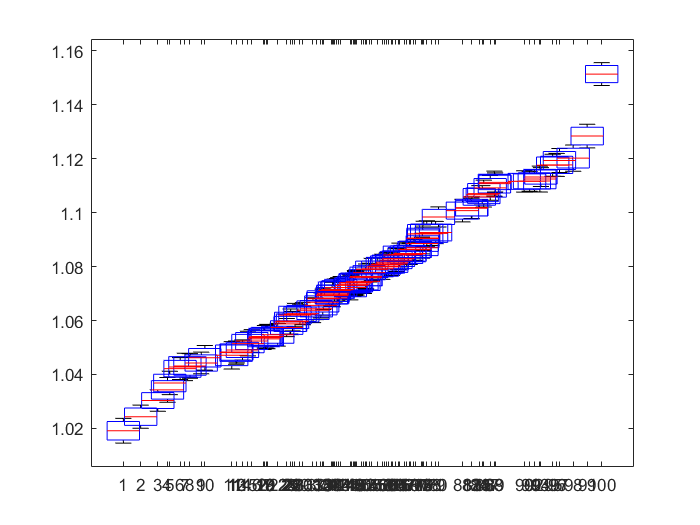

x=sort(A(1:100,1)).';
y=sort(A_hat(1:100,1)).';
data = [(sort(A_hat(1:100,1))-errbar(1:100,1)).'; sort(A_hat(1:100,1)).'; (sort(A_hat(1:100,1))+errbar(1:100,1)).'];
yneg=errors.';

% box plot
boxplot(data, 'positions', x, 'widths', 0.2);

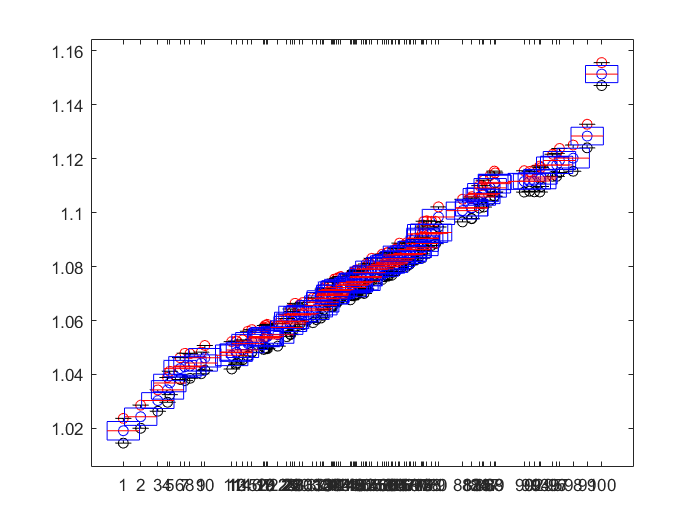

x=sort(A(1:100,1)).';
y=sort(A_hat(1:100,1)).';
data = [(sort(A_hat(1:100,1))-errbar(1:100,1)).'; sort(A_hat(1:100,1)).'; (sort(A_hat(1:100,1))+errbar(1:100,1)).'];
yneg=errors.';

% box plot
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1)),'b');
hold on
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1))+errbar(1:100,1),'r');
hold on
scatter(sort(A(1:100,1)),sort(A_hat(1:100,1))-errbar(1:100,1),'black');
hold on
boxplot(data, 'positions', x, 'widths', 0.2);
hold off

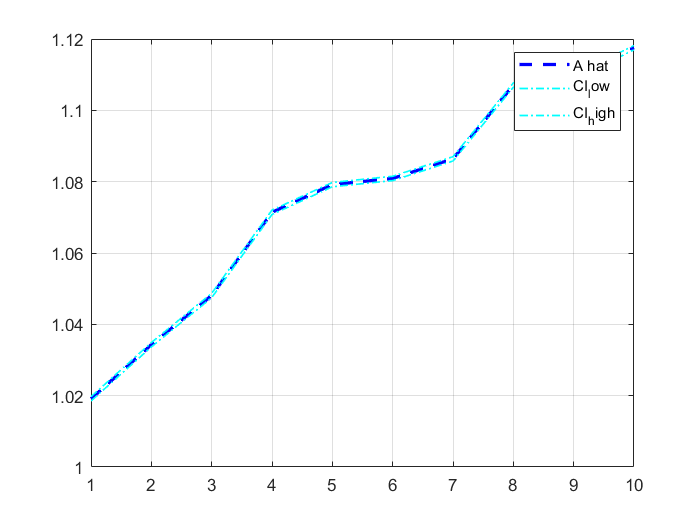


% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = A_hat(1:10,1) - CI;
CI_high = A_hat(1:10,1) + CI;

% Plot 
figure
plot(sort(A_hat(1:10,1)), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('A hat', 'CI_low', 'CI_high')
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

num_repeats = 100;
errors1= zeros(num_repeats, 1);
for i = 1:num_repeats
    A1 = 1 + sqrt(0.6)*randn(100,1000);
    X1 = 3 + sqrt(0.1)*randn(1000,1);
    % Generate new random noise
    N2 = randn(100,1);
    % Recompute Y
    Y1 = A1*X1 + N2;
    % Recompute X_ls and error
    A_hat1 = Y1*pinv(X1);
    y_hat1=A_hat1*X1;
    errors1(i) = norm(Y1 - y_hat1)/norm(Y1);
end

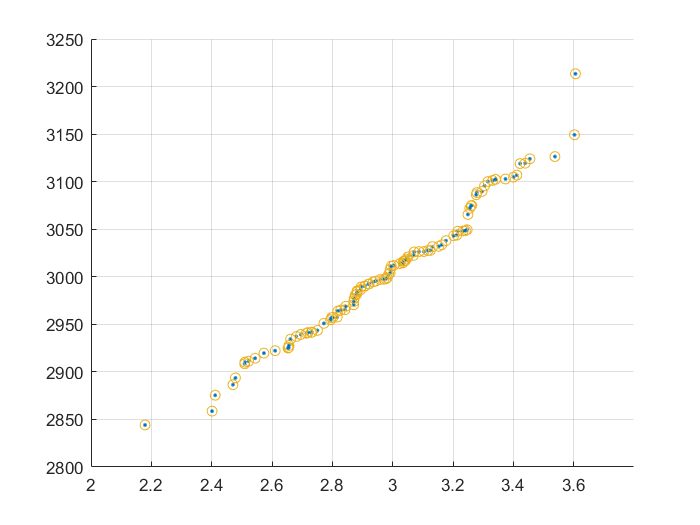

cov_y_hat=((errors1'*errors1)*(X'*X)^-1)/(100-1);
errbar=sqrt(diag(X*cov_y_hat*X'));
u=X(1:100,1);

figure;
scatter(sort(u),sort(y_hat),'.');
hold on
scatter(sort(u),sort(y_hat)+errbar(1:100,1));
hold on
scatter(sort(u),sort(y_hat)-errbar(1:100,1));
grid
hold off

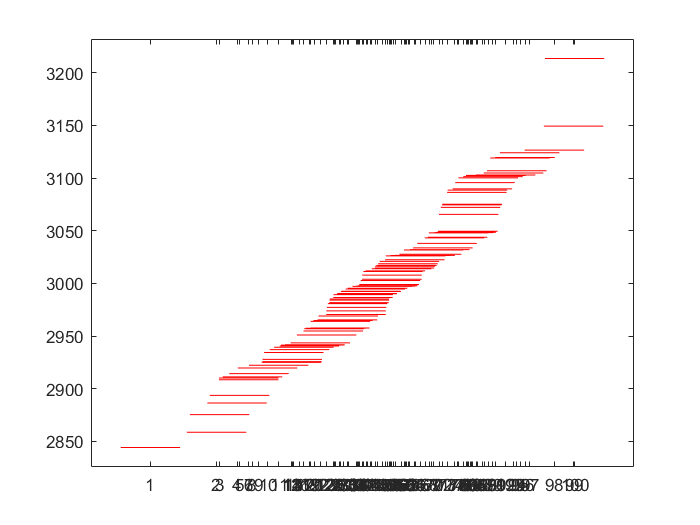

x=sort(u).';
y=sort(y_hat).';
data = [(sort(y_hat)-errbar(1:100,1)).'; sort(y_hat).'; (sort(y_hat)+errbar(1:100,1)).'];
yneg=errors.';

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.2);

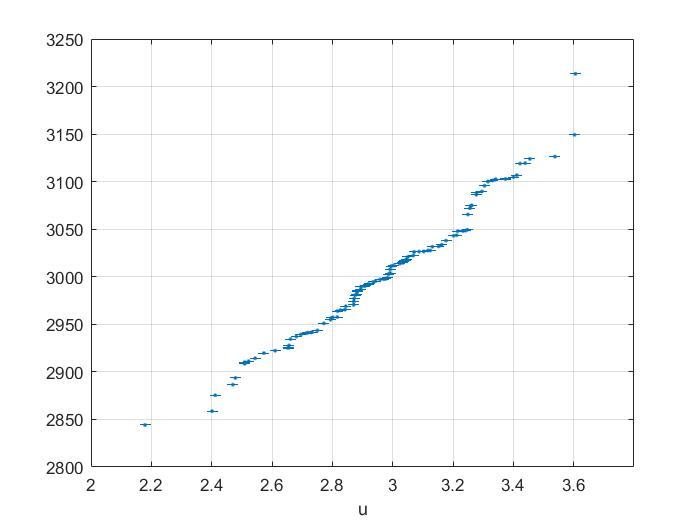

% the covariance matrix 
cov_y_hat = ((errors' * errors) * (X' * X)^-1) / (100 - 1);
se1 = sqrt(diag(X * cov_y_hat * X'));

% confidence interval
alpha = 0.05;
z = norminv(1 - alpha/2);
ci = z * se1;

%plot
u_sorted = sort(u);
y_hat_sorted = sort(y_hat);
errbar_sorted = sort(errbar);

figure;

errorbar(u_sorted, y_hat_sorted, ci(1:100,:), '.');
grid on;

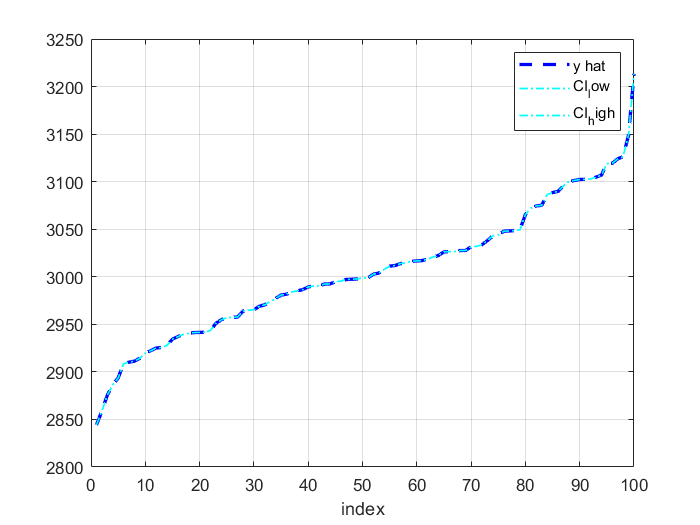


% Calculate the confidence interval
CI = 1.96 * std(errors1) / sqrt(length(errors1));
CI_low = y_hat - CI;
CI_high = y_hat + CI;

% Plot 
figure
plot(sort(y_hat), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y hat', 'CI_low', 'CI_high')
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


s=rng;
X1=hilb(1000);
rng(s);
Y=A*X+N;
% % % fist part
%%%%%%%%%%%%%
A_hat1=Y*pinv(X);
err1=norm(A-A_hat1,2)/norm(A,2);
disp(["Fist error (A-A_hat) for old X = ",num2str(err1)])

    "Fist error (A-A_hat) for old X = "    "0.13579"



%%%%%%%%%%%%%
Y1=A*X1+N;
A_hat2=Y1*inv(X1);

err2=norm(A-A_hat2,2)/norm(A,2);
disp(["Second error (A-A_hat) for new X= ",num2str(err2)])

    "Second error (A-A_hat) for new X= "    "167267228483.0887"



%%%%%%%%%%%%%
alfa=0.1;
A_hat3=Y1*(X1'*(X1*X1'+alfa*eye(1000))^-1);
err3=norm(A-A_hat3,2)/norm(A,2);
disp(["Third error (A-A_hat) for alfa method= ",num2str(err3)])

    "Third error (A-A_hat) for alfa method= "    "0.9644"




% % % second part
%%%%%%%%%%%%%
A_hat1=Y*pinv(X);
Y_hat11=A_hat1*X;
er1=norm(Y-Y_hat11)/norm(Y,2);
disp(["Fist error (Y-Y_hat) for old X = ",num2str(er1)])

    "Fist error (Y-Y_hat) for old X = "    "3.758e-16"



%%%%%%%%%%%%%
Y1=A*X1+N;
A_hat7=Y1*inv(X1);

Y_hat5=A_hat7*X;
er2=norm(Y1-Y_hat5)/norm(Y1,2);
disp(["Second error (Y-Y_hat) for new X= ",num2str(er2)])

    "Second error (Y-Y_hat) for new X= "    "1219426992893.547"



%%%%%%%%%%%%%
alfa=0.1;
A_hat33=Y1*(X1'*(X1*X1'+alfa*eye(1000))^-1);
Y_hat33=A_hat33*X1;
er3=norm(Y1-Y_hat33,2)/norm(Y1,2);
disp(["Third error (Y-Y_hat) for alfa method= ",num2str(er3)])

    "Third error (Y-Y_hat) for alfa method= "    "0.17131"



num_repeats = 100;
errors11 = zeros(num_repeats, 1);
for i = 1:num_repeats
    A = 1 + sqrt(0.6)*randn(100,1000);
    X = hilb(1000);
    % Generate new random noise
    N2 = randn(100,1);
    % Recompute Y
    Y = A*X + N2;
    % Recompute X_ls and error
    A_hat33=Y*(X'*(X*X'+alfa*eye(1000))^-1);
    errors11(i) = norm(A - A_hat33)/norm(A);
end



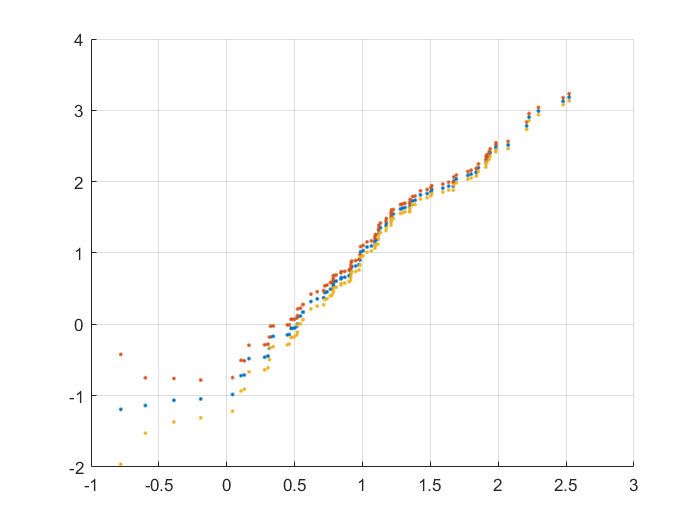

cov_A_hat=((errors11'*errors11)*(X1*X1'+alfa*eye(1000))^-1)/(100-1);
errbar=sqrt(diag(X1*cov_A_hat*X1'));
u=X1(1:100,1);

figure;
scatter(sort(A(1:100,1)),sort(A_hat33(1:100,1)),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat33(1:100,1))+errbar(1:100,1),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat33(1:100,1))-errbar(1:100,1),'.');
grid
hold off

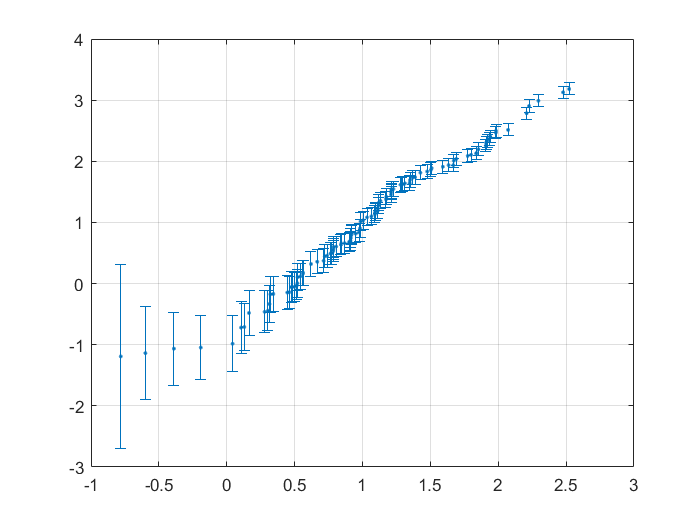


% Calculate the 95% confidence interval
alpha = 0.05;
z = norminv(1 - alpha/2);
ci = z * errbar;

% plot 
A_sorted = sort(A(1:100,1));
A_hat_sorted = sort(A_hat33(1:100,1));
errbar_sorted = sort(errbar);

figure;
errorbar(A_sorted, A_hat_sorted, ci(1:100,:), '.');
grid on;

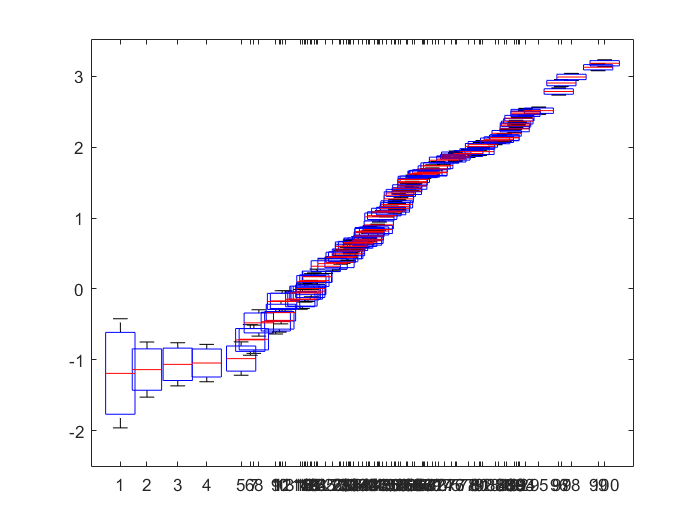

x=sort(A(1:100,1)).';
y=sort(A_hat33(1:100,1)).';
data = [(sort(A_hat33(1:100,1))-errbar(1:100,1)).'; sort(A_hat33(1:100,1)).'; (sort(A_hat33(1:100,1))+errbar(1:100,1)).'];
yneg=errors11.';

% box plot
boxplot(data, 'positions', x, 'widths', 0.2);

% % % % % % % % % % % % % % % % % 

num_repeats = 100;
errors1= zeros(num_repeats, 1);
for i = 1:num_repeats
    A1 = 1 + sqrt(0.6)*randn(100,1000);
    X1 =hilb(1000);
    % Generate new random noise
    N2 = randn(100,1);
    % Recompute Y
    Y1 = A1*X1 + N2;
    % Recompute X_ls and error
    A_hat33=Y1*(X1'*(X1*X1'+alfa*eye(1000))^-1);
    y_hat1=A_hat33*X1;
    errors1(i) = norm(Y1 - y_hat1)/norm(Y1);
end

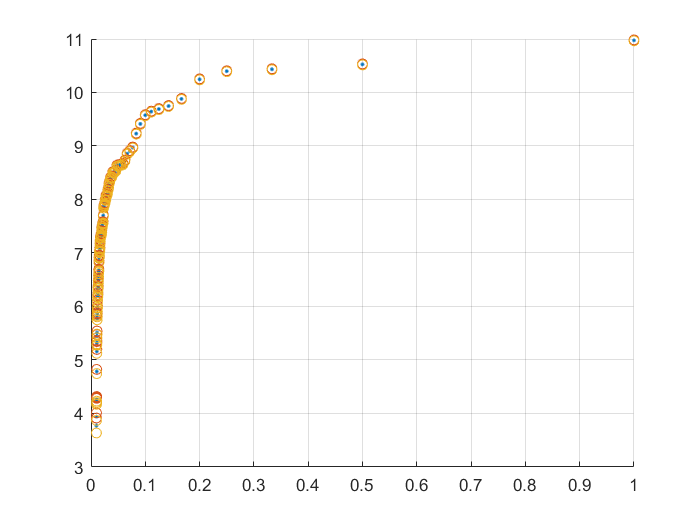

cov_y_hat=((errors1'*errors1)*(X1*X1'+alfa*eye(1000))^-1)/(100-1);
errbar=sqrt(diag(X1*cov_y_hat*X1'));
u=X1(1:100,1);

figure;
scatter(sort(u),sort(y_hat(1:100,1)),'.');
hold on
scatter(sort(u),sort(y_hat(1:100,1))+errbar(1:100,1));
hold on
scatter(sort(u),sort(y_hat(1:100,1))-errbar(1:100,1));
grid
hold off

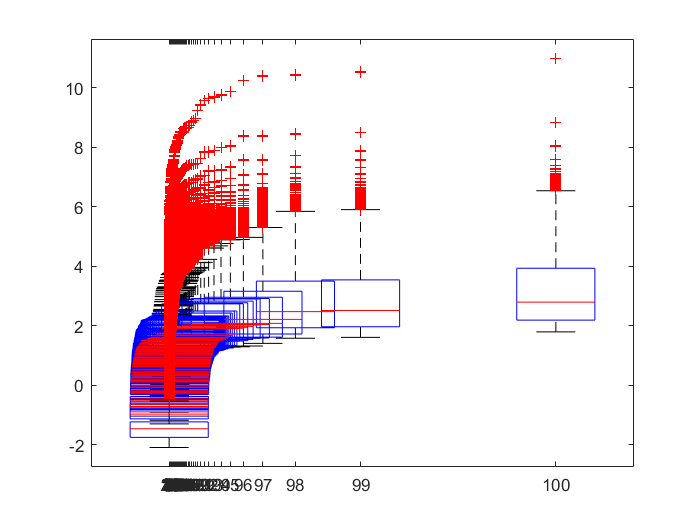

x=sort(u).';
y=sort(y_hat).';
data = [(sort(y_hat)-errbar(1:100,1)).'; sort(y_hat).'; (sort(y_hat)+errbar(1:100,1)).'];
yneg=errors11.';

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.2);

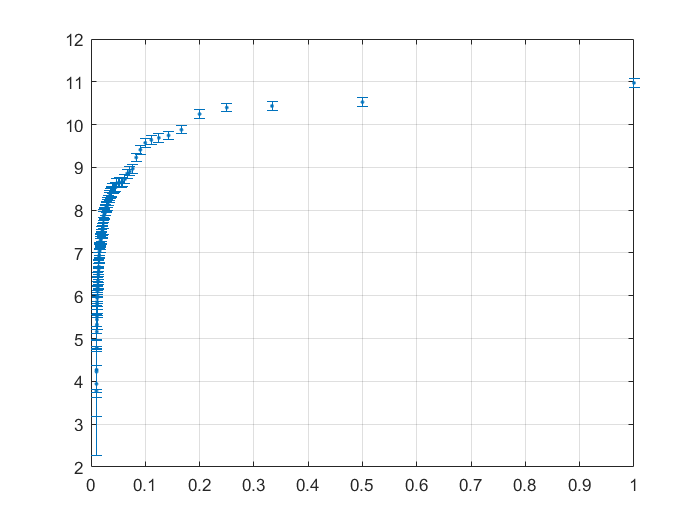

% the covariance matrix 
cov_y_hat = ((errors11' * errors11) * (X1*X1'+alfa*eye(1000))^-1) / (100 - 1);
se1 = sqrt(diag(X * cov_y_hat * X'));

% confidence interval
alpha = 0.05;
z = norminv(1 - alpha/2);
ci = z * se1;

%plot
u_sorted = sort(u);
y_hat_sorted = sort(y_hat);
errbar_sorted = sort(errbar);

figure;

errorbar(u_sorted, y_hat_sorted(1:100,1), ci(1:100,:), '.');
grid on;

y_hat=A_hat33*X1;
Y = A*X1 + N;
error=norm(Y-y_hat)/norm(Y);
disp(["Model error= ",num2str(error)])

    "Model error= "    "0.7017"



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


s=rng;
X1=hilb(1000);
rng(s);
Y=A*X+N;
XX=X1(1:1000,1)

XX =     1.0000
    0.5000
    0.3333
    0.2500
    0.2000
    0.1667
    0.1429
    0.1250
    0.1111
    0.1000


% % % fist part
%%%%%%%%%%%%%
A_hat1=Y*pinv(X);
err1=norm(A-A_hat1,2)/norm(A,2);
disp(["Fist error (A-A_hat) for old X = ",num2str(err1)])

    "Fist error (A-A_hat) for old X = "    "0.1372"



%%%%%%%%%%%%%
Y1=A*XX+N;
A_hat2=Y1*pinv(XX);
err2=norm(A-A_hat2,2)/norm(A,2);
disp(["Second error (A-A_hat) for new X= ",num2str(err2)])

    "Second error (A-A_hat) for new X= "    "0.98355"




% % % second part
%%%%%%%%%%%%%
A_hat1=Y*pinv(X);
Y_hat11=A_hat1*X;
er1=norm(Y-Y_hat11)/norm(Y,2);
disp(["Fist error (Y-Y_hat) for old X = ",num2str(er1)])

    "Fist error (Y-Y_hat) for old X = "    "4.0054e-16"



%%%%%%%%%%%%%
Y1=A*XX+N;
A_hat7=Y1*pinv(XX);
Y_hat5=A_hat7*XX;
er2=norm(Y1-Y_hat5)/norm(Y1,2);
disp(["Second error (Y-Y_hat) for new X= ",num2str(er2)])

    "Second error (Y-Y_hat) for new X= "    "7.9599e-16"



num_repeats = 100;

errors = zeros(num_repeats, 1);
for i = 1:num_repeats
    A1 = 1 + sqrt(0.6)*randn(100,1000);
    X1 = XX;
    % Generate new random noise
    N2 = randn(100,1);
    % Recompute Y
    Y1 = A1*X1 + N2;
    % Recompute X_ls and error
    A_hat1 = Y1*pinv(X1);
    errors(i) = norm(A1 - A_hat1)/norm(A1);
end







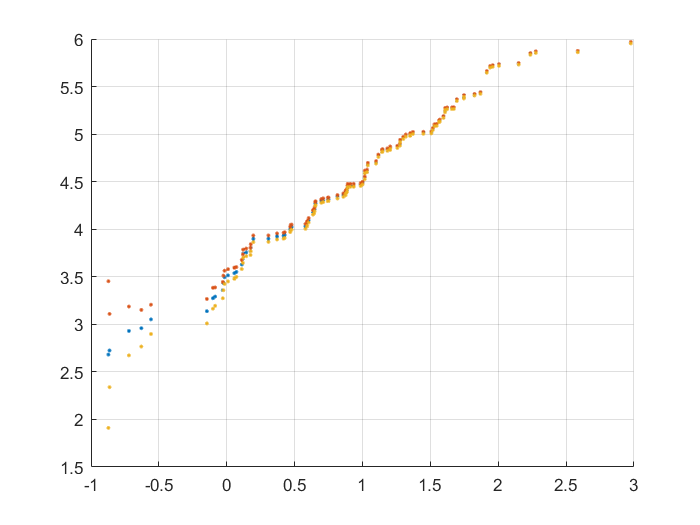

cov_A_hat=((errors'*errors)*(XX'*XX)^-1)/(100-1);
errbar=sqrt(diag(XX*cov_A_hat*XX'));
u=X(1:100,1);

figure;
scatter(sort(A(1:100,1)),sort(A_hat2(1:100,1)),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat2(1:100,1))+errbar(1:100,1),'.');
hold on
scatter(sort(A(1:100,1)),sort(A_hat2(1:100,1))-errbar(1:100,1),'.');
grid
hold off

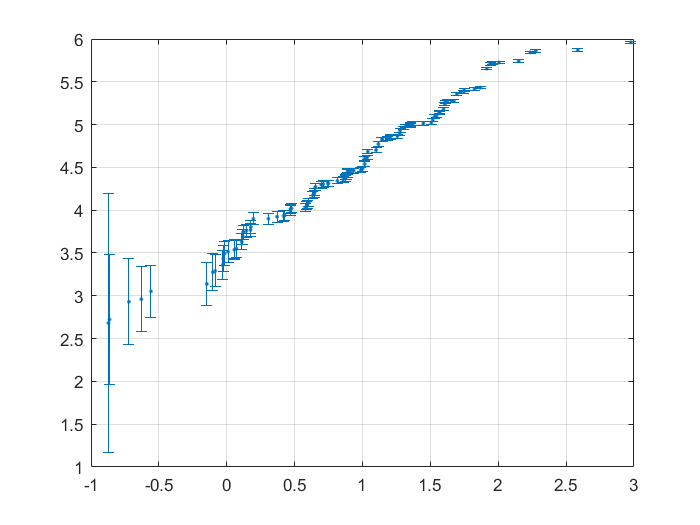


% Calculate the 95% confidence interval
alpha = 0.05;
z = norminv(1 - alpha/2);
ci = z * errbar;

% plot 
A_sorted = sort(A(1:100,1));
A_hat_sorted = sort(A_hat2(1:100,1));
errbar_sorted = sort(errbar);

figure;
errorbar(A_sorted, A_hat_sorted, ci(1:100,:), '.');
grid on;

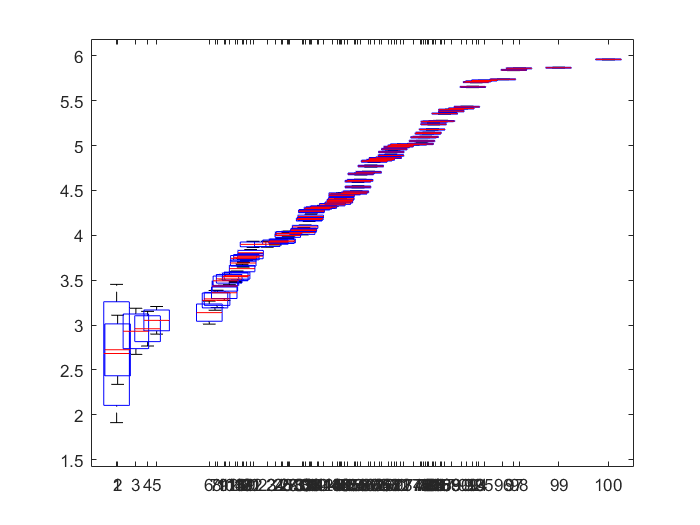

x=sort(A(1:100,1)).';
y=sort(A_hat2(1:100,1)).';
data = [(sort(A_hat2(1:100,1))-errbar(1:100,1)).'; sort(A_hat2(1:100,1)).'; (sort(A_hat2(1:100,1))+errbar(1:100,1)).'];
yneg=errors.';

% box plot
boxplot(data, 'positions', x, 'widths', 0.2);

y_hat=A_hat2*XX;
Y = A*XX + N;
error=norm(Y-y_hat)/norm(Y);
disp(["Model error= ",num2str(error)])

    "Model error= "    "7.9599e-16"



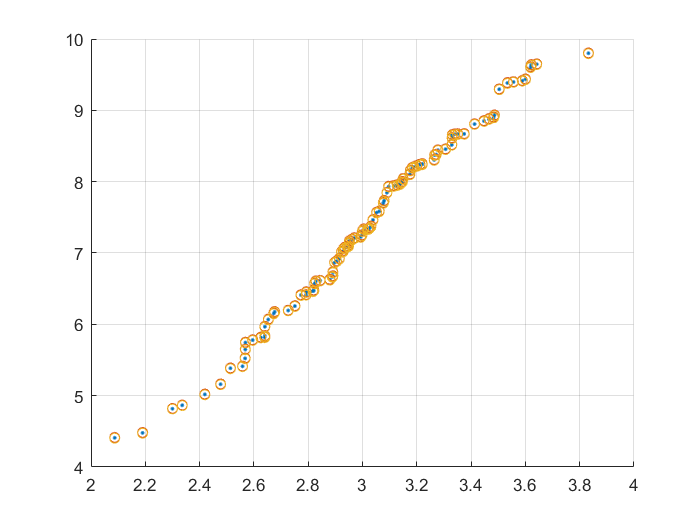

cov_y_hat=((errors1'*errors1)*(X'*X)^-1)/(100-1);
errbar=sqrt(diag(X*cov_y_hat*X'));
u=X(1:100,1);

figure;
scatter(sort(u),sort(y_hat),'.');
hold on
scatter(sort(u),sort(y_hat)+errbar(1:100,1));
hold on
scatter(sort(u),sort(y_hat)-errbar(1:100,1));
grid
hold off

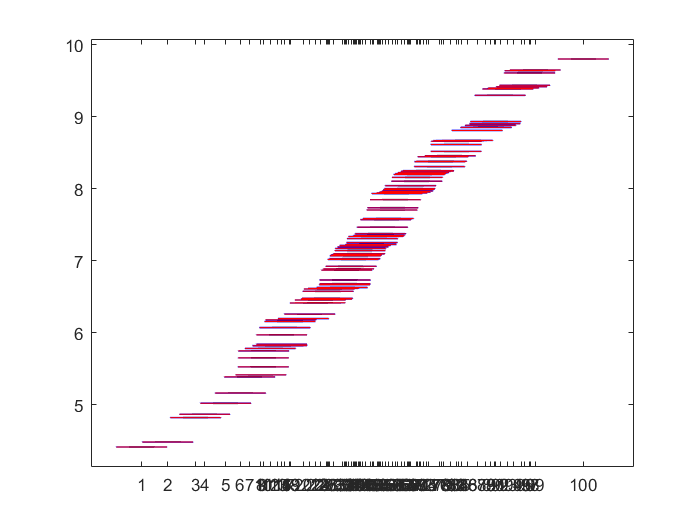

x=sort(u).';
y=sort(y_hat).';
data = [(sort(y_hat)-errbar(1:100,1)).'; sort(y_hat).'; (sort(y_hat)+errbar(1:100,1)).'];
yneg=errors.';

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.2);

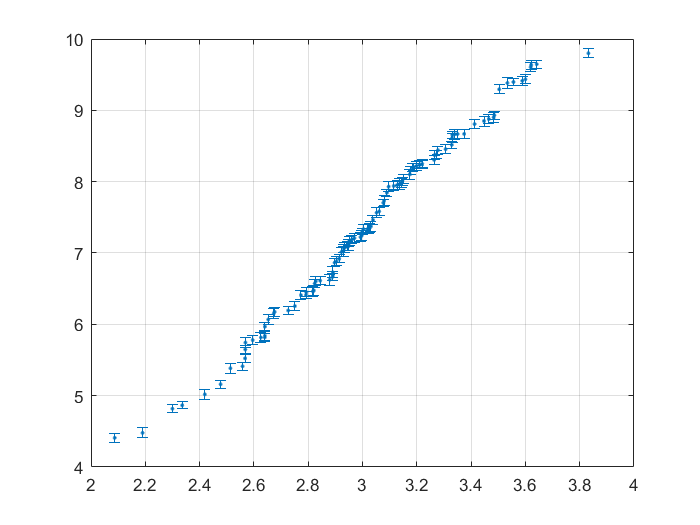

% the covariance matrix 
cov_y_hat = ((errors' * errors) * (X' * X)^-1) / (100 - 1);
se1 = sqrt(diag(X * cov_y_hat * X'));

% confidence interval
alpha = 0.05;
z = norminv(1 - alpha/2);
ci = z * se1;

%plot
u_sorted = sort(u);
y_hat_sorted = sort(y_hat);
errbar_sorted = sort(errbar);

figure;

errorbar(u_sorted, y_hat_sorted, ci(1:100,:), '.');
grid on;

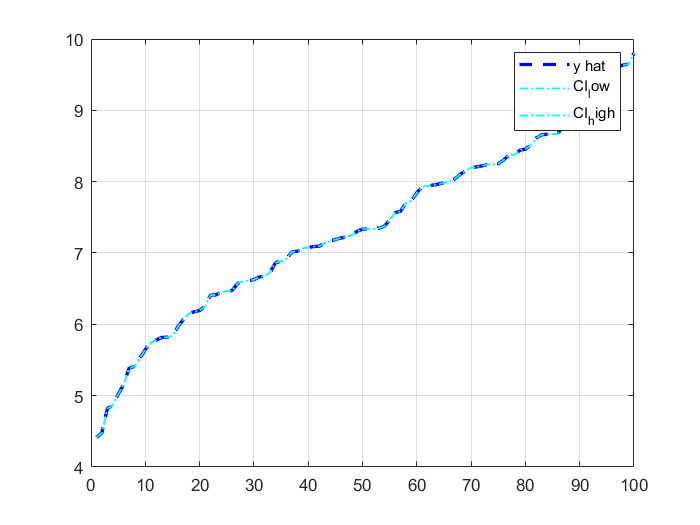


% Calculate the confidence interval
CI = 1.96 * std(errors1) / sqrt(length(errors1));
CI_low = y_hat - CI;
CI_high = y_hat + CI;

% Plot 
figure
plot(sort(y_hat), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y hat', 'CI_low', 'CI_high')
hold off